# 2D-Fourier Transform

In this section we will implement the 2D Fourier Transform on images and learn about some of its properties.

1. 1 the 2D FFT 

The equations for the FFT and iFFT for an image I of size $M\times N$ are as follows:


$$F\left\lbrace I\left(m,n\right)\right\rbrace \left(u,v\right)=\;\sum_{m=0}^{M-1} \sum_{n=0}^{N-1} I\left(m,n\right)\cdot e^{-2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$


and the inverse transform:


$$I\left(m,n\right)=\frac{1}{M\cdot N}\sum_{u=0}^{M-1} \sum_{v=0}^{N-1} F\left(u,v\right)\cdot e^{2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$


accounting to MATLAB's indexing, we will rewrite the array indices as such: 


$$F\left(u+1,v+1\right)=\;\sum_{m=0}^{M-1} \sum_{n=0}^{N-1} I\left(m+1,n+1\right)\cdot e^{-2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$



$$I\left(m+1,n+1\right)=\frac{1}{M\cdot N}\sum_{u=0}^{M-1} \sum_{v=0}^{N-1} F\left(u+1,v+1\right)\cdot e^{2\pi i\left(\frac{u\cdot m}{M}+\frac{v\cdot n}{N}\right)}$$



$$F\left(u+1,v+1\right)=\;\sum_{m=0}^{M-1} \left(\sum_{n=0}^{N-1} I\left(m+1,n+1\right)\cdot e^{-2\pi i\left(\frac{v\cdot n}{N}\right)} \right)e^{-2\pi i\left(\frac{u\cdot m}{M}\right)}$$


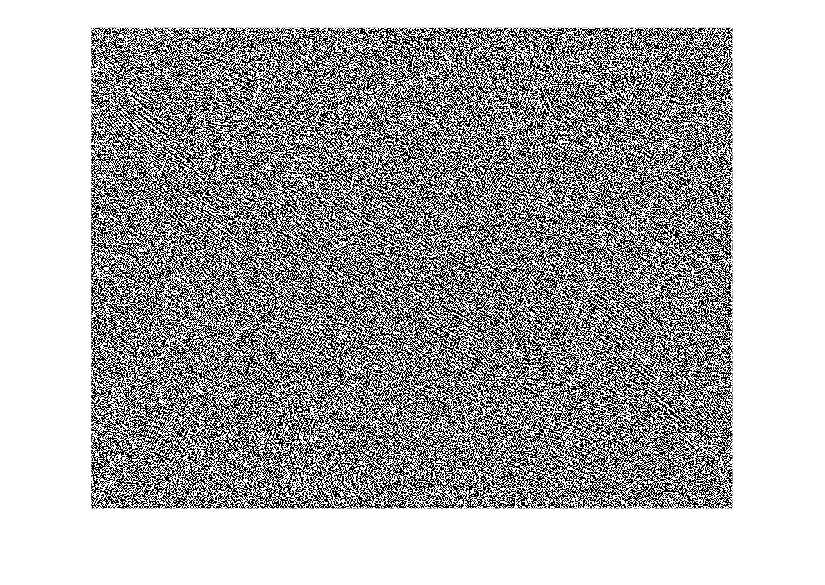

I = imread_normalized("beatles.png");

my_FFT = dip_fft2(I);
F = fft2(I);
imshow(my_FFT)

imshow(F)

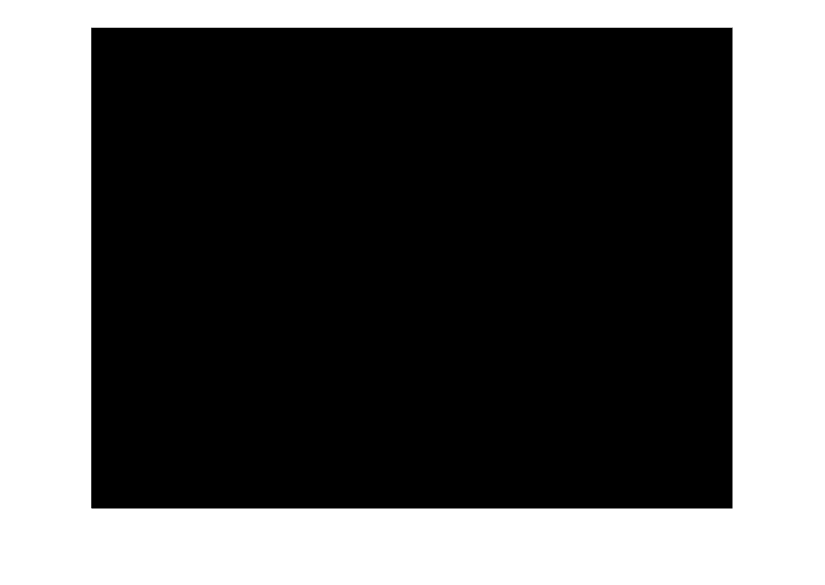

imshow(F-my_FFT)


% compute MSE
mse = mean(mean((F - my_FFT) .^ 2))

mse = 3.2491e-21 + 6.5516e-22i


img = dip_ifft2(my_FFT)

img =    0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 + 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 + 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 + 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i   0.5059 - 0.0000i
   0.5059 - 0.0000i   0.5059 + 0.0000i   0.

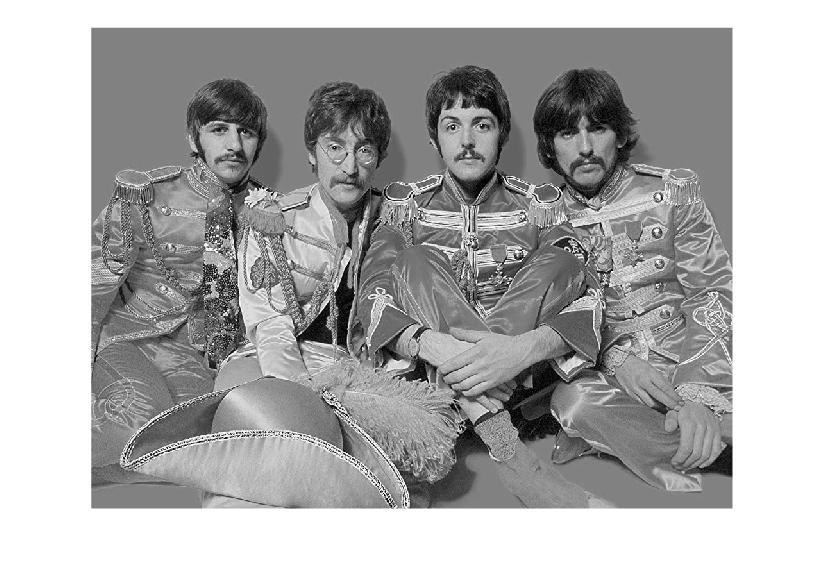

imshow(img)